% read data from simulation
t = out.x_tip.Time;
x = squeeze(out.x_tip.Data);
y = squeeze(out.y_tip.Data);

% m to mm units
t = t(:);
x = x(:) * 1000;
y = y(:) * 1000;

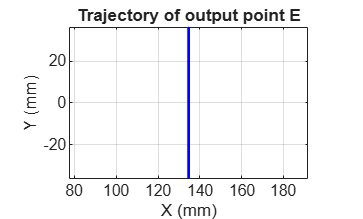

% Plot trajectory x,y
figure;
plot(x, y, 'b-', 'LineWidth', 1.5);
axis equal;
grid on;
xlabel('X (mm)');
ylabel('Y (mm)');
title('Trajectory of output point E');

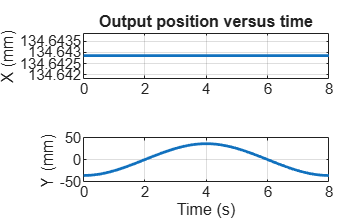


% Plot positions vs time
figure;
subplot(2,1,1);
plot(t, x, 'LineWidth', 1.5);
xlim([0 8]);
ylim(x_theory + [-0.001 0.001]); % ±0.01 mm

grid on;
ylabel('X (mm)');
title('Output position versus time');

subplot(2,1,2);
plot(t, y, 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Y (mm)');